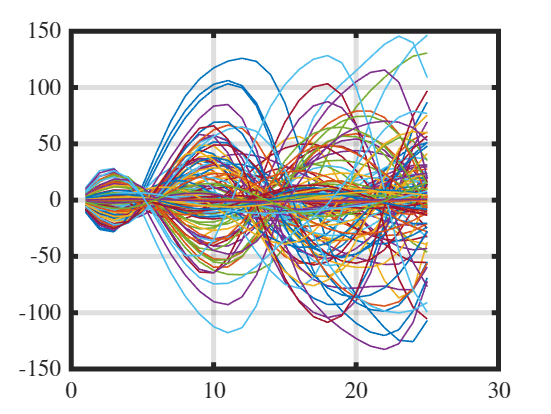

clear; close all;
rng(1);

% Number of runs
K = 25;
% Number references per run
W = 5;
% Number samples in a trial
N = 25;
% Reference cell
rc = cell(W,K);
% Inital inputs
uc = cell(W,K);
% Iterate runs
for k = 1:K
    % Iterate references
    w = 1;
    while(true)
        % Input variance
        u_var = 0.8*rand(1);
        % Random input
        u = u_var* randn(N, 1);
        % Butterworth-Filter
        [b,a] = butter(4, 0.1);
        % Filter
        u = filtfilt(b, a, u);
        % Apply to dynamics
        r = run_double_pendulum_feedforward_dynamics(u);
        rc{w,k} = r;
        % Inital input
        uc{w,k} = 0.05*randn(N,1);
        % Check reference boundary
        if(sum(abs(r)>deg2rad(180))==0)
            w = w + 1;
            % Plot
            plot(rad2deg(r), 'LineWidth', 1); hold on;
        end
        % Check final condition
        if(w > W)
            break;
        end
    end
end